# DIFERENCIAS FINITAS NO LINEAL DIRICHLET

function [X,Y,Yprime,iter,incr] = Difnolin_ND(f,fy,fz,a,b,alfa,beta,N,maxiter,tol,solver)
% Resuelve EDO no lineal con condiciones de contorno no Dirichlet usando diferencias finitas
% f = f(x,y,z) - ecuación diferencial de segundo orden
% fy = derivada parcial de f respecto y
% fz = derivada parcial de f respecto z (y'=z)
% [a,b] - intervalo
% alfa, beta - condiciones de contorno
% N - número de puntos internos
% maxiter - máximo de iteraciones
% tol - tolerancia
% solver - 'Crout' o 'Thomas' para seleccionar método

h = (b-a)/(N+1);
k = (beta-alfa)/(N+1);
X = a:h:b; 
Y = alfa:k:beta;

x = X(1:N+2); 
y = Y(1:N+2);

incr = tol + 1;
iter = 0;

while incr > tol && iter < maxiter
    % Estimación de la derivada
    z = (Y(3:N+2)-Y(1:N))/(2*h);
    z = [(3*Y(1)-alfa)/2 z (6*Y(end)-3*beta)];
    
    % Evaluar funciones
    fe = f(x,y,z);
    fye = fy(x,y,z);
    fze = fz(x,y,z);
    
    % Construcción de la matriz tridiagonal
    dp = 2 + h^2*fye; % Diagonal principal
    dp(1) = 2 + 3*h + h^2*fye(1) + 3*h^2*fze(1)/2;
    dp(end) = (2 - 12*h) + h^2*fye(end) + 6*h^2*fze(end);
    
    ds = -1 + h/2*fze(1:end-1); % Diagonal superior
    ds(1) = -2;
    
    di = -1 - h/2*fze(2:end); % Diagonal inferior
    di(end) = -2;
    
    % Vector -F[y^k]
    d = zeros(N+2,1);
    d(2:N+1) = -(-diff(Y,2) + h^2*fe(2:N+1));
    d(1) = -(-2*y(2) + (2+3*h)*y(1) + h^2*fe(1) - h*alfa);
    d(N+2) = -(-2*y(N+1) + (2-12*h)*y(N+2) + h^2*fe(N+2) + 6*beta*h);
    
    % Selección del solver
    switch lower(solver)
        case 'crout'
            v = Crout(dp, ds, di, d);
        case 'thomas'
            v = Thomas(dp, ds, di, d);
        otherwise
            error('Solver no reconocido. Usar "Crout" o "Thomas"');
    end
    
    y = y + v';
    Y = y;
    incr = max(abs(v));
    iter = iter + 1;
end

% Cálculo de las derivadas
Yprime = zeros(size(Y));
for i = 2:length(Y)-1
    Yprime(i) = (Y(i+1)-Y(i-1))/(2*h);
end
Yprime(1) = (3*Y(1)-alfa)/2;
Yprime(end) = 3*(2*Y(end)-beta);

% Formatear salidas
X = X(:);
Y = Y(:);
Yprime = Yprime(:);
end



function sol= Crout (a,b,c,d)
% a diagonal principal , b superdiagonal , c ...
%subdiagonal , d terminos independiante
n= length (a);
% Obtencion de las matrices L y U tales que A = LU
l(1)=a(1);
u(1)=b(1)/l(1);
for i=2:n -1
l(i)=a(i)-c(i -1)*u(i -1);
u(i)=b(i)/l(i);
end
l(n)=a(n)-c(n -1)*u(n -1);
% Solucion del sistema Lz = d
z(1)=d(1)/l(1);
for i=2:n
z(i)=(1/ l(i))*(d(i)-c(i -1)*z(i -1));
end
% Solucion del sistema Ux = z
x(n)=z(n);
for i=n -1: -1:1
x(i)=z(i)-u(i)*x(i+1);
end
sol=x(:);
end


% Método de Gausss para matrices tridiagonales
function x = Thomas(a,b,c,d)
n = length(a);
% Eliminación hacia adelante
for i = 2:n
    m = c(i-1)/a(i-1);
    a(i) = a(i) - m*b(i-1);
    d(i) = d(i) - m*d(i-1);
end

% Sustitución hacia atrás
x = zeros(n,1);
x(n) = d(n)/a(n);

for i = n-1:-1:1
    x(i) = (d(i) - b(i)*x(i+1))/a(i);
end
end

EJECUCIÓN

f=@(x,y,z) x.*y.*z - 3.*y.^2 +6.*x;
fy=@(x,y,z) x.*z - 6.*y;
fz=@(x,y,z) x.*y;
a=0;b=1;
alfa=0;beta=1;
N=99;  %num d subintervalo es lo q divide h=(b-a)/N+1
maxiter=50;
tol=1e-5;
[X,Y,Yprime,iter,incr]=Difnolin_ND(f,fy,fz,a,b,alfa,beta,N,maxiter,tol,'Crout');
[X_thomas, Y_thomas, Yprime_thomas, iter_thomas, incr_thomas] = Difnolin_ND(f,fy,fz,a,b,alfa,beta,N,maxiter,tol,'Thomas');

COMPARACIÓN

table(X,Y,Yprime)

ans = 101×3 table
     X          Y           Yprime  
    ____    __________    __________

       0    4.4956e-05    6.7435e-05
    0.01    4.5631e-05    0.00036743
    0.02    5.2305e-05     0.0012674
    0.03    7.0979e-05     0.0027674
    0.04    0.00010765     0.0048674
    0.05    0.00016833     0.0075674
    0.06      0.000259      0.010867
    0.07    0.00038568      0.014767
    0.08    0.00055435      0.019267
    0.09    0.00077103      0.024367
     0.1     0.0010417      0.030067
    0.11     0.0013724      0.036367
    0.12      0.001769      0.043267
    0.13     0.0022377      0.050767
    0.14     0.0027844      0.058867
    0.15     0.0034151      0.067567


iter

iter = 4

incr

incr = 5.7403e-07

table(X_thomas, Y_thomas, Yprime_thomas)

ans = 101×3 table
    X_thomas     Y_thomas     Yprime_thomas
    ________    __________    _____________

         0      4.4956e-05     6.7435e-05  
      0.01      4.5631e-05     0.00036743  
      0.02      5.2305e-05      0.0012674  
      0.03      7.0979e-05      0.0027674  
      0.04      0.00010765      0.0048674  
      0.05      0.00016833      0.0075674  
      0.06        0.000259       0.010867  
      0.07      0.00038568       0.014767  
      0.08      0.00055435       0.019267  
      0.09      0.00077103       0.024367  
       0.1       0.0010417       0.030067  
      0.11       0.0013724       0.036367  
      0.12        0.001769       0.043267  
      0.13       0.0022377       0.050767  
      0.14       0.0027844       0.058867  
      0.15       0.0034151       0.067567  


iter_thomas

iter_thomas = 4

incr_thomas

incr_thomas = 5.7403e-07

% Comparar resultados
dif_Y = norm(Y - Y_thomas);
dif_Yprime = norm(Yprime - Yprime_thomas);


## `Comparación de métodos:`

fprintf('Crout: iteraciones = %d, incr final = %.2e\n', iter, incr);

Crout: iteraciones = 4, incr final = 5.74e-07


fprintf('Thomas: iteraciones = %d, incr final = %.2e\n', iter_thomas, incr_thomas);

Thomas: iteraciones = 4, incr final = 5.74e-07


fprintf('Diferencia en Y: %.2e\n', dif_Y);

Diferencia en Y: 1.06e-14


fprintf('Diferencia en Yprime: %.2e\n', dif_Yprime);

Diferencia en Yprime: 1.83e-14


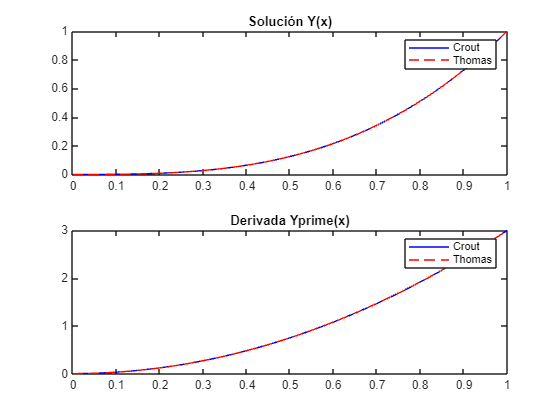



% Graficar resultados
subplot(2,1,1)
plot(X, Y, 'b', X_thomas, Y_thomas, 'r--')
title('Solución Y(x)')
legend('Crout', 'Thomas')

subplot(2,1,2);
plot(X, Yprime, 'b', X_thomas, Yprime_thomas, 'r--')
title('Derivada Yprime(x)')
legend('Crout', 'Thomas');